# Creation of a small GUI to show sensor data

By Johannes Sutter and Adei Garmendia Garcia

23.11.2024

Initial Setup

clear;
clc;
close all;
cd(fileparts(matlab.desktop.editor.getActiveFilename))
%%%%% openExample('matlab/AppdMemoryMonitorExample') %%%%


Generation of random sensor values within 0cm and 50cm

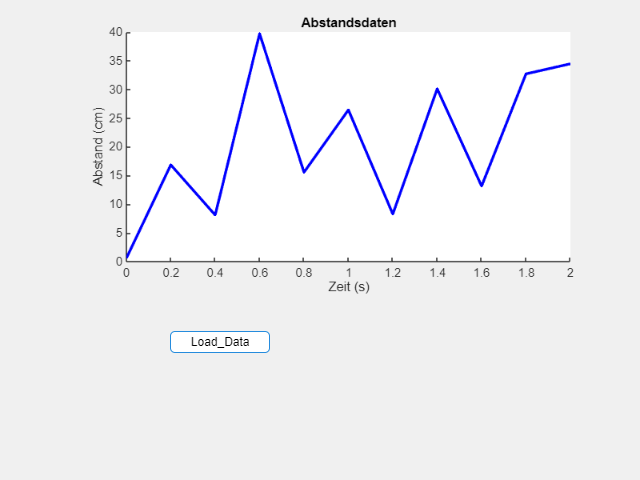

% Samples = 100; 
% sensorData = 50 * rand(1, Samples);
% sensorTime = 0:0.002:0.198;
% sensorData = round(sensorData, 2);
% sensorTime = round(sensorTime, 2);
% assignin('base', 'sensorData', sensorData);
% assignin('base', 'sensorTime', sensorTime);

T = timer('TimerFcn',@(~,~)disp('Fired.'),'StartDelay',0.2);
run('Show_sensor_data.mlapp')

i=6;
k=1;
sensorTime(k)=0

sensorTime = 0

sensorData(k) = 50 * rand(1, 1);
while i>1
    k=k+1;
    sensorData(k) = 50 * rand(1, 1);
    sensorTime(k) = 0.2+sensorTime(k-1);
    assignin('base', 'sensorData', sensorData);
    assignin('base', 'sensorTime', sensorTime);
    start(T)
    wait(T)
end


